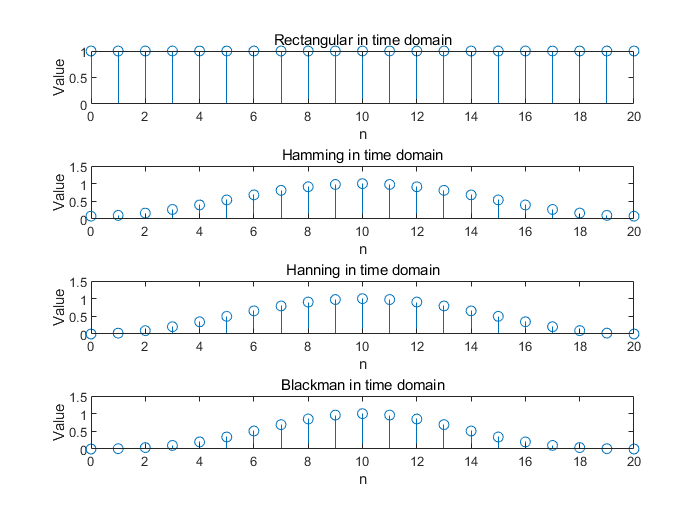

%8.2
N1=21;
rectangular=ones(1,N1);
Hamming=hamming(N1);
Hanning=hann(N1);
Blackman=blackman(N1);
figure
subplot(4,1,1);
stem(0:N1-1,rectangular);
xlabel("n");
ylabel("Value");
title("Rectangular in time domain");
subplot(4,1,2);
stem(0:N1-1,Hamming);
xlabel("n");
ylabel("Value");
title("Hamming in time domain");
axis([0 20 0 1.5]);
subplot(4,1,3);
stem(0:N1-1,Hanning);
xlabel("n");
ylabel("Value");
title("Hanning in time domain");
axis([0 20 0 1.5]);
subplot(4,1,4);
stem(0:N1-1,Blackman);
xlabel("n");
ylabel("Value");
title("Blackman in time domain");
axis([0 20 0 1.5]);

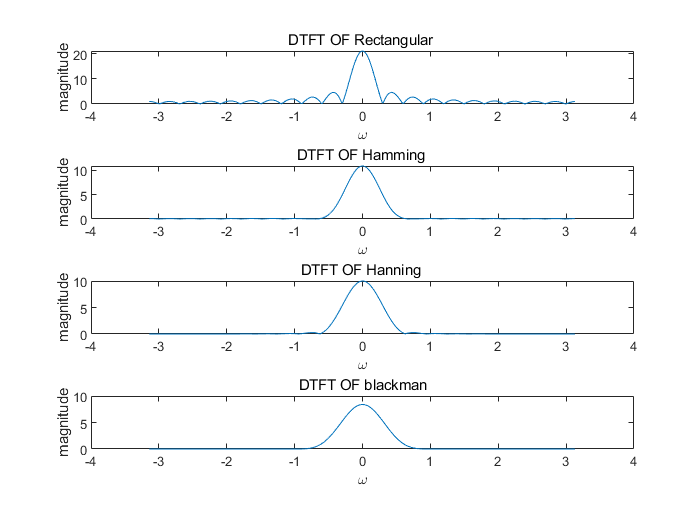


[Xofrectangular,wofrectangular]=DTFT(rectangular,512);
[Xofhamming,wofhamming]=DTFT(Hamming,512);
[Xofhanning,wofhanning]=DTFT(Hanning,512);
[Xofblackman,wofblackman]=DTFT(Blackman,512);

figure
subplot(4,1,1);
plot(wofrectangular,abs(Xofrectangular));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF Rectangular ");
%axis([-4 4 -60 40]);
subplot(4,1,2);
plot(wofhamming,abs(Xofhamming));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF Hamming ");
%axis([-4 4 -60 40]);
subplot(4,1,3);
plot(wofhanning,abs(Xofhanning));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF Hanning ");
%axis([-4 4 -100 50]);
subplot(4,1,4);
plot(wofblackman,abs(Xofblackman));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF blackman");

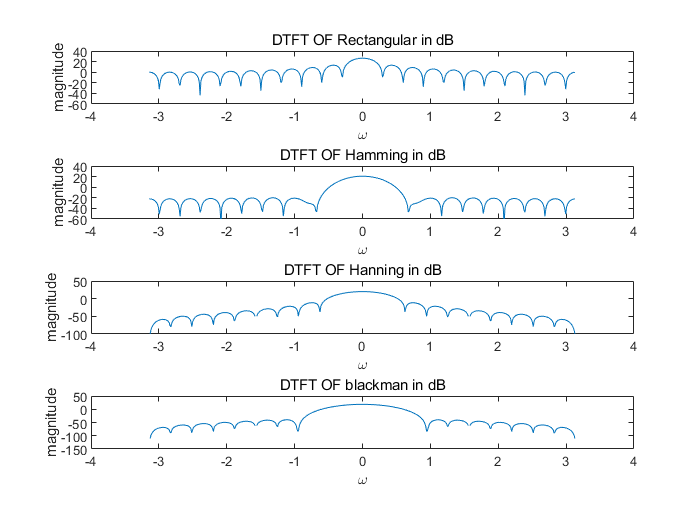

%axis([-4 4 -150 50]);

figure
subplot(4,1,1);
plot(wofrectangular,20*log10(abs(Xofrectangular)));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF Rectangular in dB");
axis([-4 4 -60 40]);
subplot(4,1,2);
plot(wofhamming,20*log10(abs(Xofhamming)));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF Hamming in dB");
axis([-4 4 -60 40]);
subplot(4,1,3);
plot(wofhanning,20*log10(abs(Xofhanning)));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF Hanning in dB");
axis([-4 4 -100 50]);
subplot(4,1,4);
plot(wofblackman,20*log10(abs(Xofblackman)));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF blackman in dB");
axis([-4 4 -150 50]);

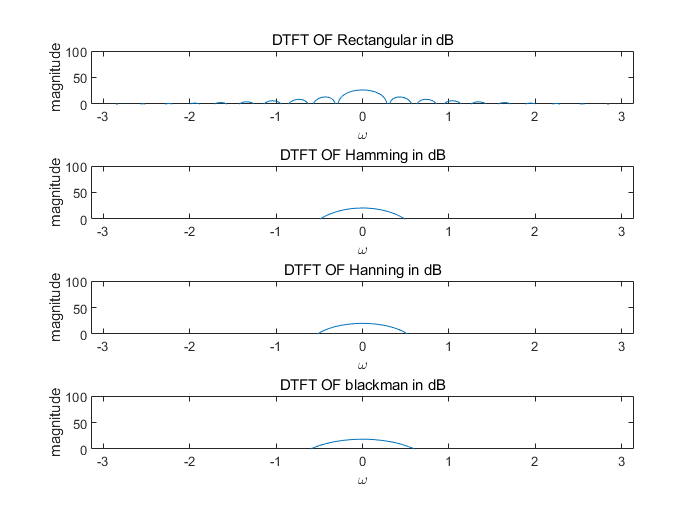


figure
subplot(4,1,1);
plot(wofrectangular,20*log10(abs(Xofrectangular)));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF Rectangular in dB");
axis([-pi,pi,0,100]);
subplot(4,1,2);
plot(wofhamming,20*log10(abs(Xofhamming)));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF Hamming in dB");
axis([-pi,pi,0,100]);
subplot(4,1,3);
plot(wofhanning,20*log10(abs(Xofhanning)));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF Hanning in dB");
axis([-pi,pi,0,100]);
subplot(4,1,4);
plot(wofblackman,20*log10(abs(Xofblackman)));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF blackman in dB");
axis([-pi,pi,0,100]);

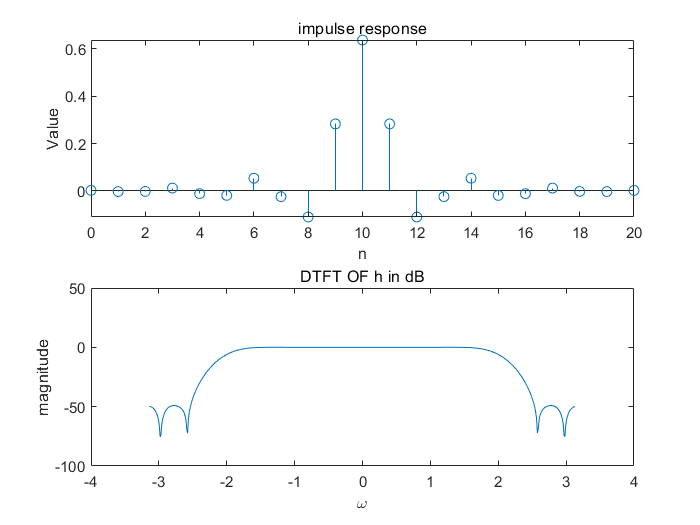


wc=2.0;
hamt=Hamming';
for i=1:21
    h(i)=hamt(i)*wc/pi*sinc(wc/pi*(i-1-(21-1)/2));
end
[Xofh,wofh]=DTFT(h,512);
figure
subplot(2,1,1);
stem(0:20,h);
xlabel("n");
ylabel("Value");
title("impulse response");
subplot(2,1,2);
plot(wofh,20*log10(abs(Xofh)));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF h in dB");
axis([-4 4 -100 50]);

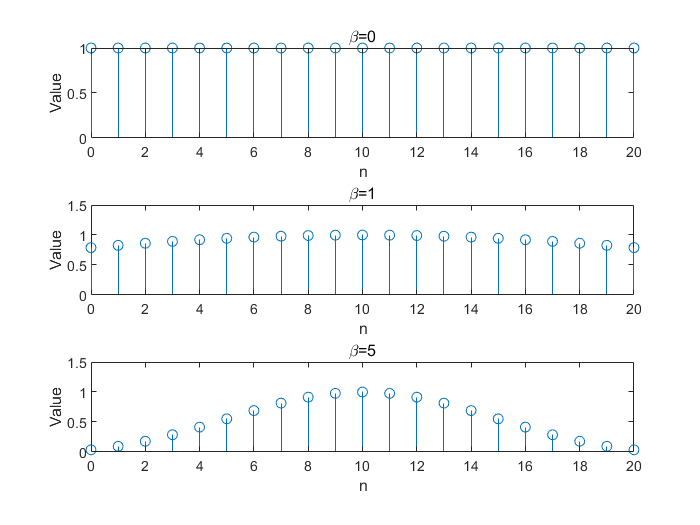


%8.3
kaiser_w1=kaiser(21,0);
kaiser_w2=kaiser(21,1);
kaiser_w3=kaiser(21,5);
figure
subplot(3,1,1);
stem(0:20,kaiser_w1);
xlabel("n");
ylabel("Value");
title("\beta=0");
subplot(3,1,2);
stem(0:20,kaiser_w2);
xlabel("n");
ylabel("Value");
title("\beta=1");
axis([0 20 0 1.5]);
subplot(3,1,3);
stem(0:20,kaiser_w3);
xlabel("n");
ylabel("Value");
title("\beta=5");
axis([0 20 0 1.5]);

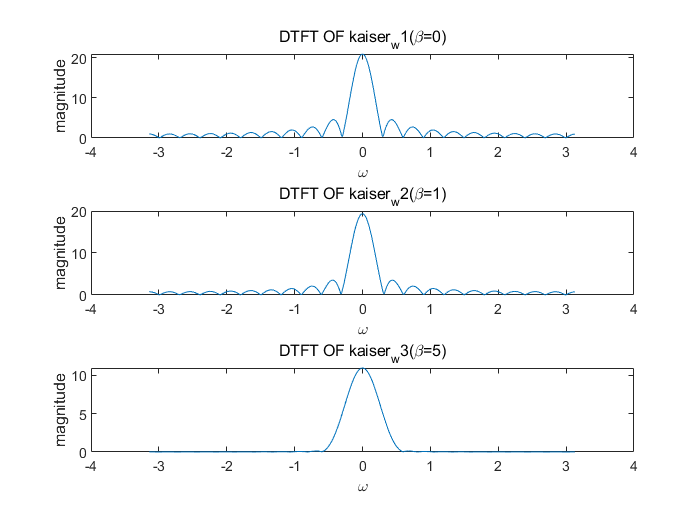


[Xofkaiser_w1,wofkaiser_w1]=DTFT(kaiser_w1,512);
[Xofkaiser_w2,wofkaiser_w2]=DTFT(kaiser_w2,512);
[Xofkaiser_w3,wofkaiser_w3]=DTFT(kaiser_w3,512);

figure
subplot(3,1,1);
plot(wofkaiser_w1,abs(Xofkaiser_w1));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF kaiser_w1(\beta=0)");
%axis([-4 4 -60 40]);
subplot(3,1,2);
plot(wofkaiser_w2,abs(Xofkaiser_w2));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF kaiser_w2(\beta=1)");
%axis([-4 4 -60 40]);
subplot(3,1,3);
plot(wofkaiser_w3,abs(Xofkaiser_w3));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF kaiser_w3(\beta=5)");

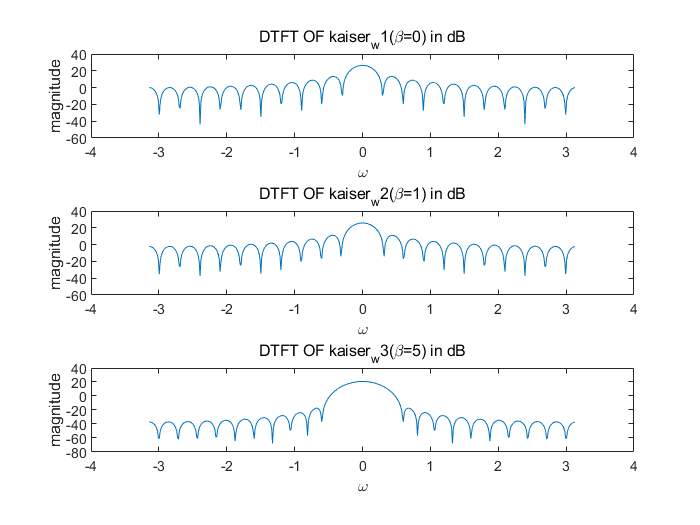

%axis([-4 4 -80 40]);


figure
subplot(3,1,1);
plot(wofkaiser_w1,20*log10(abs(Xofkaiser_w1)));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF kaiser_w1(\beta=0) in dB");
axis([-4 4 -60 40]);
subplot(3,1,2);
plot(wofkaiser_w2,20*log10(abs(Xofkaiser_w2)));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF kaiser_w2(\beta=1) in dB");
axis([-4 4 -60 40]);
subplot(3,1,3);
plot(wofkaiser_w3,20*log10(abs(Xofkaiser_w3)));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF kaiser_w3(\beta=5) in dB");
axis([-4 4 -80 40]);

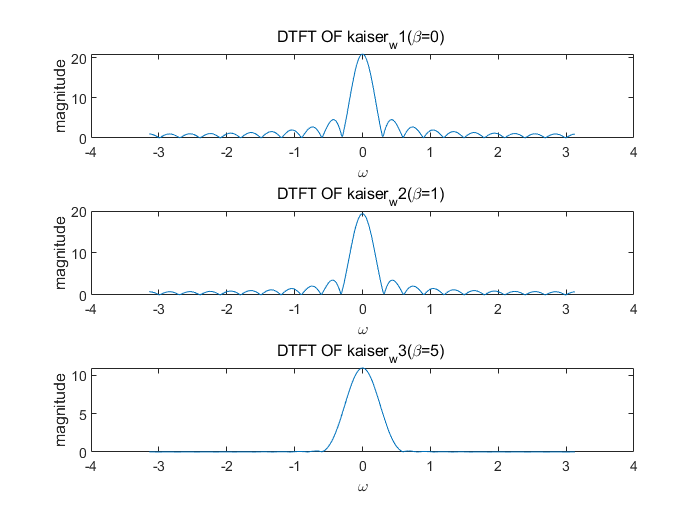


figure
subplot(3,1,1);
plot(wofkaiser_w1,abs(Xofkaiser_w1));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF kaiser_w1(\beta=0) ");
subplot(3,1,2);
plot(wofkaiser_w2,abs(Xofkaiser_w2));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF kaiser_w2(\beta=1) ");
subplot(3,1,3);
plot(wofkaiser_w3,abs(Xofkaiser_w3));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF kaiser_w3(\beta=5) ");

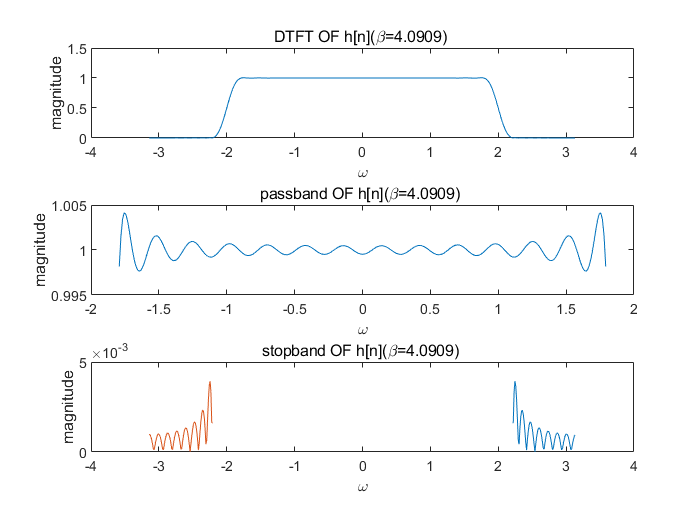


sigma=0.005;
A=-20*log10(sigma);
%A=42.0206
betaofkaiser=0.5842*(A-21)^0.4+0.07886*(A-21);
% beta=4.0909
N0fkaiser=ceil(1+(A-8)/2.285/0.4);
% N=43
kaiser_w4=kaiser(N0fkaiser,betaofkaiser);
kaiser_w4t=kaiser_w4';
for i=1:N0fkaiser
    hofkaiser_w4(i)=kaiser_w4t(i)*2.0/pi*sinc(2.0/pi*(i-1-(N0fkaiser-1)/2));
end
[Xofhofkaiser_w4,wofhofkaiser_w4]=DTFT( hofkaiser_w4,512);
figure
subplot(3,1,1);
plot(wofhofkaiser_w4,abs(Xofhofkaiser_w4));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF h[n](\beta=4.0909) ");
axis([-4 4 0 1.5]);
subplot(3,1,2);
plot(wofhofkaiser_w4(111:403),abs(Xofhofkaiser_w4(abs(wofhofkaiser_w4)<=1.8)));
xlabel("\omega");
ylabel("magnitude");
title("passband OF h[n](\beta=4.0909) ");
axis([-2 2 0.995 1.005]);
subplot(3,1,3);
plot(wofhofkaiser_w4(437:512),abs(Xofhofkaiser_w4(wofhofkaiser_w4>=2.2)));hold on
plot(wofhofkaiser_w4(1:77),abs(Xofhofkaiser_w4(wofhofkaiser_w4<=-2.2)))
axis([-4 4 0 0.005]);
xlabel("\omega");
ylabel("magnitude");
title("stopband OF h[n](\beta=4.0909) ");

[Xmaxofpassband,Imaxofpassband]=max(abs(Xofhofkaiser_w4(abs(wofhofkaiser_w4)<=1.8)));
disp(Xmaxofpassband);

    1.0041



disp(Imaxofpassband);

     4



[Xminofpassband,Iminofpassband]=min(abs(Xofhofkaiser_w4(abs(wofhofkaiser_w4)<=1.8)));
disp(Xminofpassband);

    0.9976



disp(Iminofpassband);

    13



[Xmaxofstopband,Imaxofstopband]=max(abs(Xofhofkaiser_w4(abs(wofhofkaiser_w4)>=2.2)));
disp(Xmaxofstopband);

    0.0039



disp(Imaxofstopband);

    74



[Xminofstopband,Iminofstopband]=min(abs(Xofhofkaiser_w4(abs(wofhofkaiser_w4)>=2.2)));
disp(Xminofstopband);

   1.1901e-05



disp(Iminofstopband);

    50



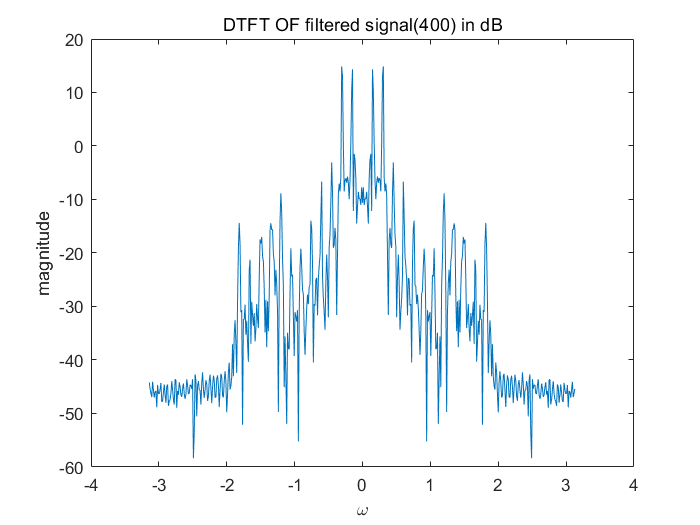


load nspeech2;
sound(nspeech2);
fiilternspeech2=conv(nspeech2,hofkaiser_w4);
sound(fiilternspeech2);
[Xoffiilternspeech2,woffiilternspeech2]=DTFT(fiilternspeech2(20001:20400),400);
figure
plot(woffiilternspeech2,20*log10(abs(Xoffiilternspeech2)));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF filtered signal(400) in dB");


%8.4
f=[1.8,2.2];
m=[1,0];
ripple=[0.05,0.005];
[noffirpmord,fo,mo,woffirpmord]=firpmord(f,m,ripple,2*pi);
disp(noffirpmord);

    25



b=firpm(noffirpmord+3,fo,mo,woffirpmord);
disp(noffirpmord+3);

    28



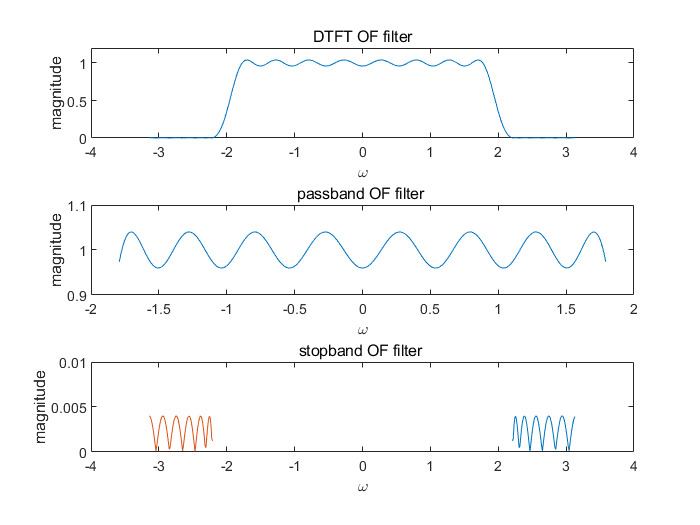

[Xoffirpm,woffirpm]=DTFT(b,512);
figure
subplot(3,1,1);
plot(woffirpm,abs(Xoffirpm));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF filter");
axis([-4 4 0 1.2]);
subplot(3,1,2);
plot(woffirpm(111:403),abs(Xoffirpm(abs(woffirpm)<=1.8)));
xlabel("\omega");
ylabel("magnitude");
title("passband OF filter ");
axis([-2 2 0.9 1.1]);
subplot(3,1,3);
plot(woffirpm(437:512),abs(Xoffirpm(woffirpm>=2.2)));hold on
plot(woffirpm(1:77),abs(Xoffirpm(woffirpm<=-2.2)))
axis([-4 4 0 0.01]);
xlabel("\omega");
ylabel("magnitude");
title("stopband OF filter ");

[Xmaxofpassbandfirpm,Imaxofpassbandfirpm]=max(abs(Xoffirpm(abs(woffirpm)<=1.8)));
disp(Xmaxofpassbandfirpm);

    1.0402



disp(Imaxofpassbandfirpm);

    43



[Xminofpassbandfirpm,Iminofpassbandfirpm]=min(abs(Xoffirpm(abs(woffirpm)<=1.8)));
disp(Xminofpassbandfirpm);

    0.9599



disp(Iminofpassbandfirpm);

    62



[Xmaxofstopbandfirpm,Imaxofstopbandfirpm]=max(abs(Xoffirpm(abs(woffirpm)>=2.2)));
disp(Xmaxofstopbandfirpm);

    0.0040



disp(Imaxofstopbandfirpm);

    33



[Xminofstopbandfirpm,Iminofstopbandfirpm]=min(abs(Xoffirpm(abs(woffirpm)>=2.2)));
disp(Xminofstopbandfirpm);

   5.2016e-05



disp(Iminofstopbandfirpm);

    56



disp(noffirpmord+3);

    28



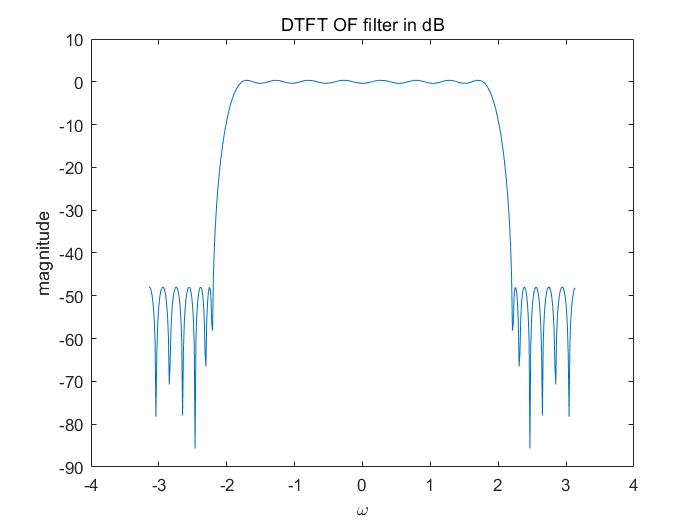


figure
plot(woffirpm,20*log10(abs(Xoffirpm)));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF filter in dB");

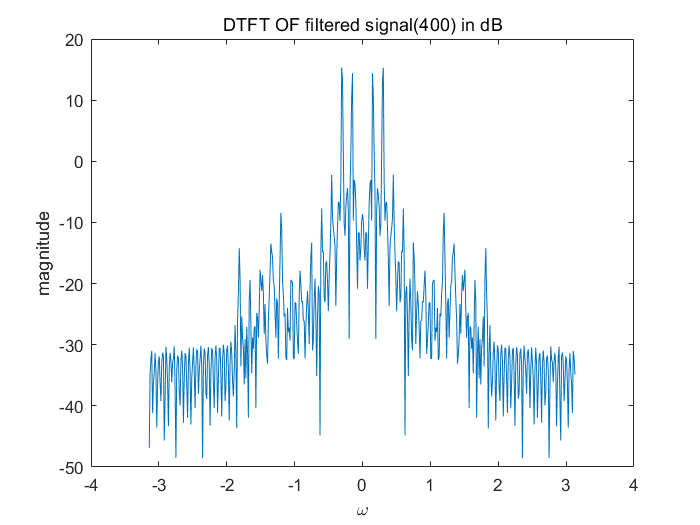


fiilternspeech2offirpm=conv(nspeech2,b);
sound(fiilternspeech2offirpm);
[Xoffiilternspeech2offirpm,woffiilternspeech2offirpm] = DTFT(fiilternspeech2offirpm(20001:20400), 400);
figure
plot(woffiilternspeech2offirpm,20*log10(abs(Xoffiilternspeech2offirpm)));
xlabel("\omega");
ylabel("magnitude");
title("DTFT OF filtered signal(400) in dB");